# Diffraction limited optics

The spatial resolution of an ideal optical system is limited only by diffraction.  We can specify the diffraction in terms of the point spread function of that system. For a circular aperture, we can calculate the diffraction limited point spread function as a function of wavelength. The diffraction-limited point spread function is calculated here and illustrated for various simple cases.

**See also: **

oiCreate, oiCompute, oiSet, oiPlot

ieInit

## Create a point array scene

Each point will produce an image of the point spread.  We make a pretty small scene with many samples so you can visualize the point spread.  Zoom the image in the display, and notice the colored fringes!

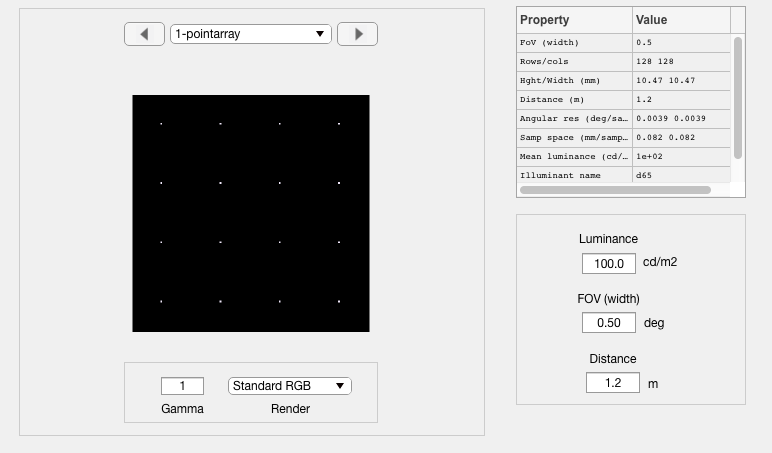

sz = [128 128]; spacing = 32;
scene = sceneCreate('point array',sz,spacing);
scene = sceneSet(scene,'h fov',0.5);    % Degrees
sceneWindow(scene);

## Compute the irradiance

The default f/# is 4.0.  Have a look.

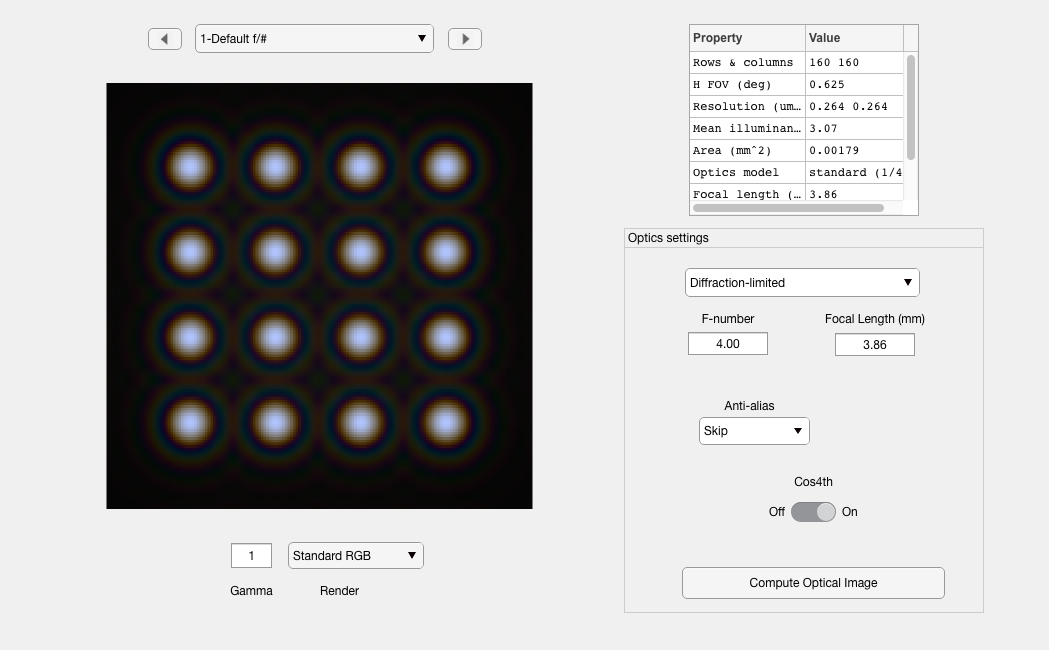

oi = oiCreate;
oi = oiCompute(oi,scene);
oi = oiSet(oi,'name','Default f/#');
oiWindow(oi);

## Diffraction limited optics with f/# = 12

The larger f/# blurs the image more, but it has larger depth of field, however, because the aperture is smaller.  This is not shown in this picture because all the points are in the same depth plane.

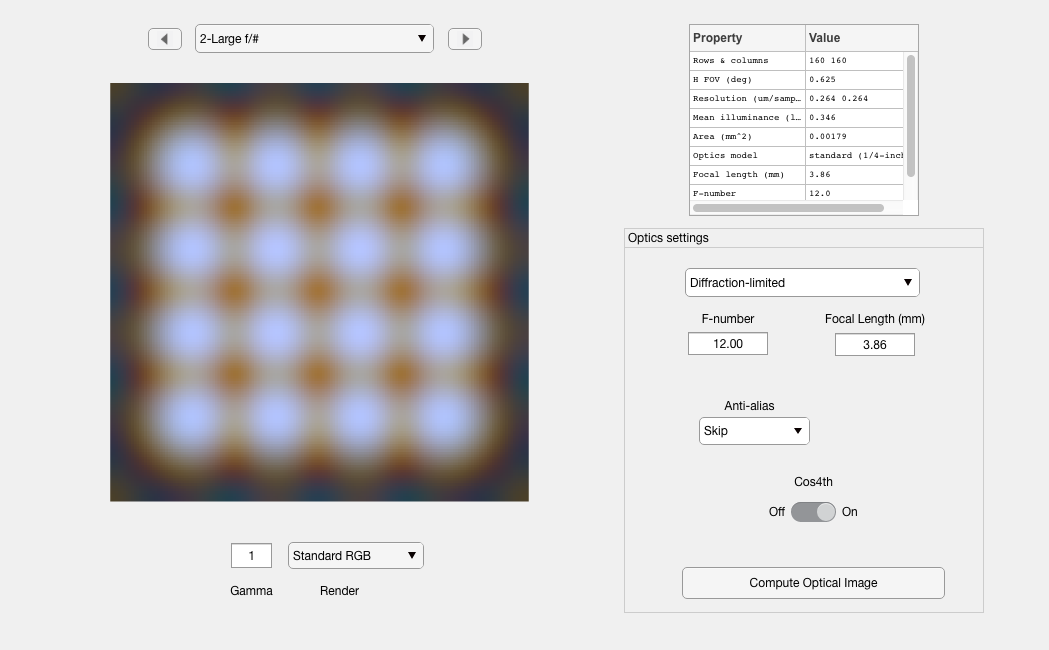

oi2 = oiSet(oi,'optics fnumber',12);
oi2 = oiCompute(oi2,scene);
oi2 = oiSet(oi2,'name','Large f/#');
oiWindow(oi2);

## Print out the 3-parameters

p = oiGet(oi,'optics pupil diameter','mm')

p = 0.9657

f = oiGet(oi,'optics focal length','mm')

f = 3.8628

oiGet(oi,'optics f number') 

ans = 4

f/p

ans = 4

## The psf for the two f/#

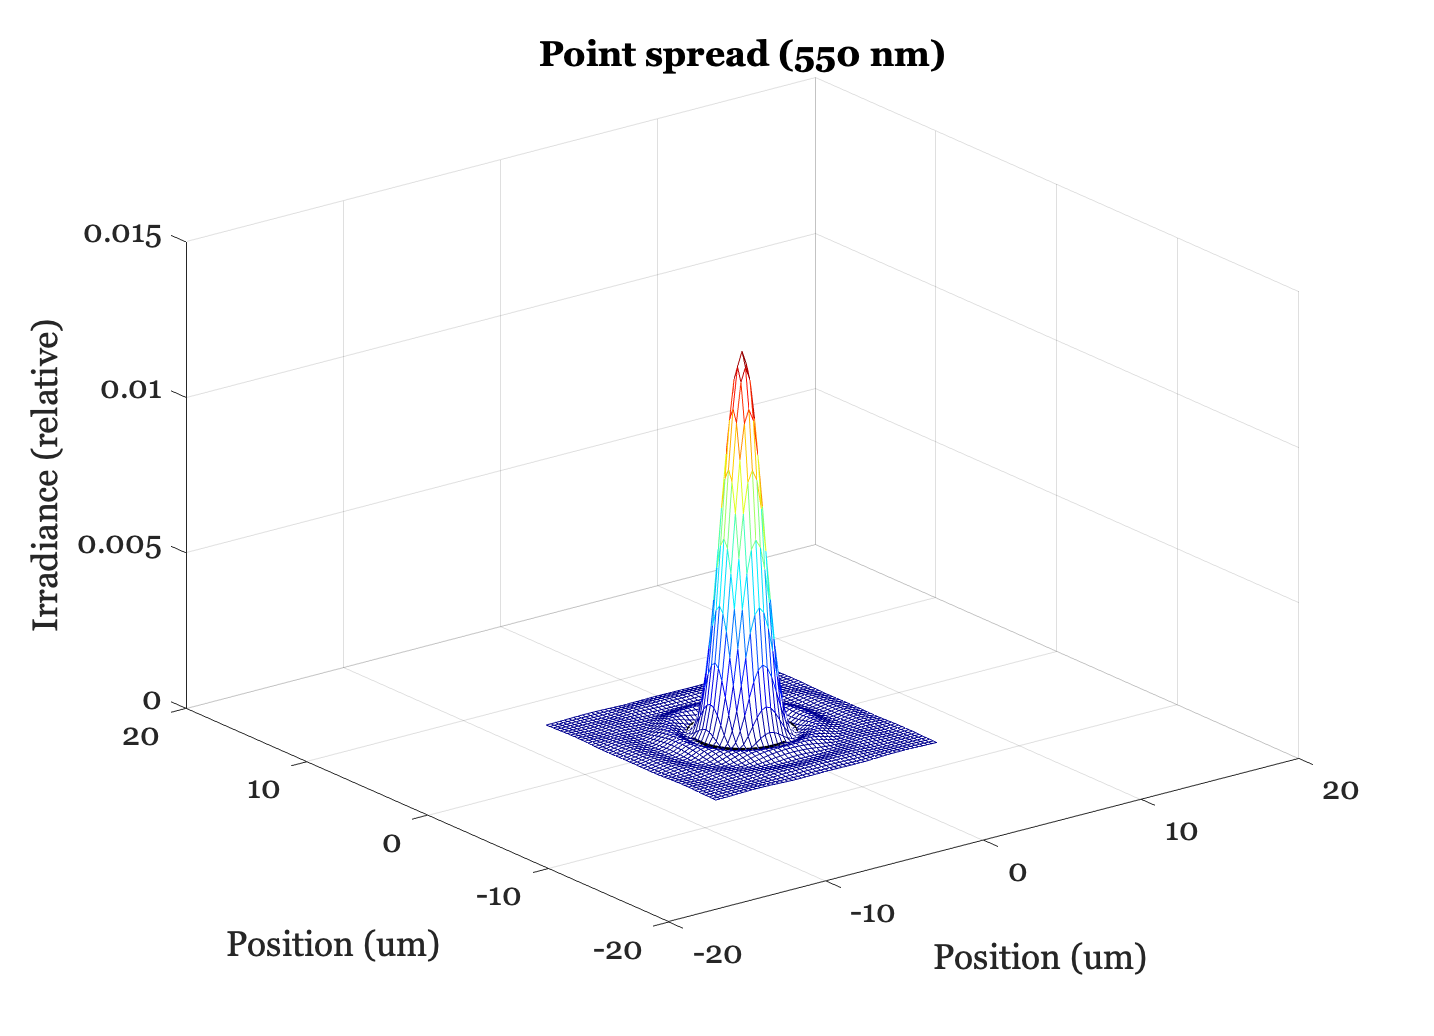

oiPlot(oi,'psf 550'); set(gca,'xlim',[-20 20],'ylim',[-20 20])

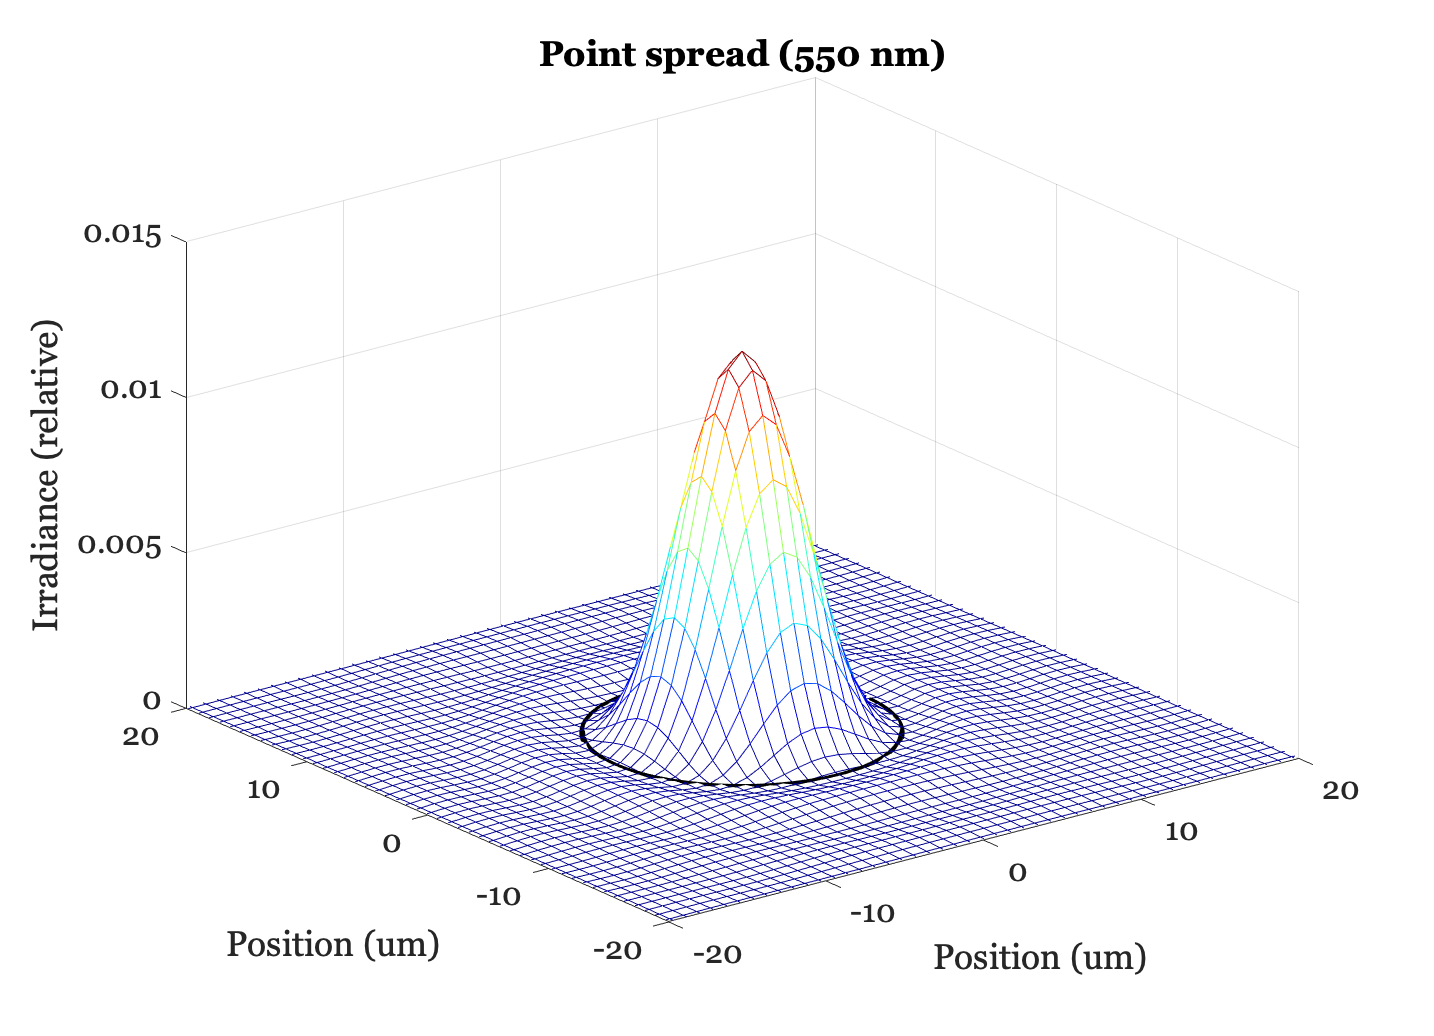

oiPlot(oi2,'psf 550');set(gca,'xlim',[-20 20],'ylim',[-20 20])

## The diffraction-limited blur dependence on wavelength

The short wavelengths have a wider linespread than the long wavelengths

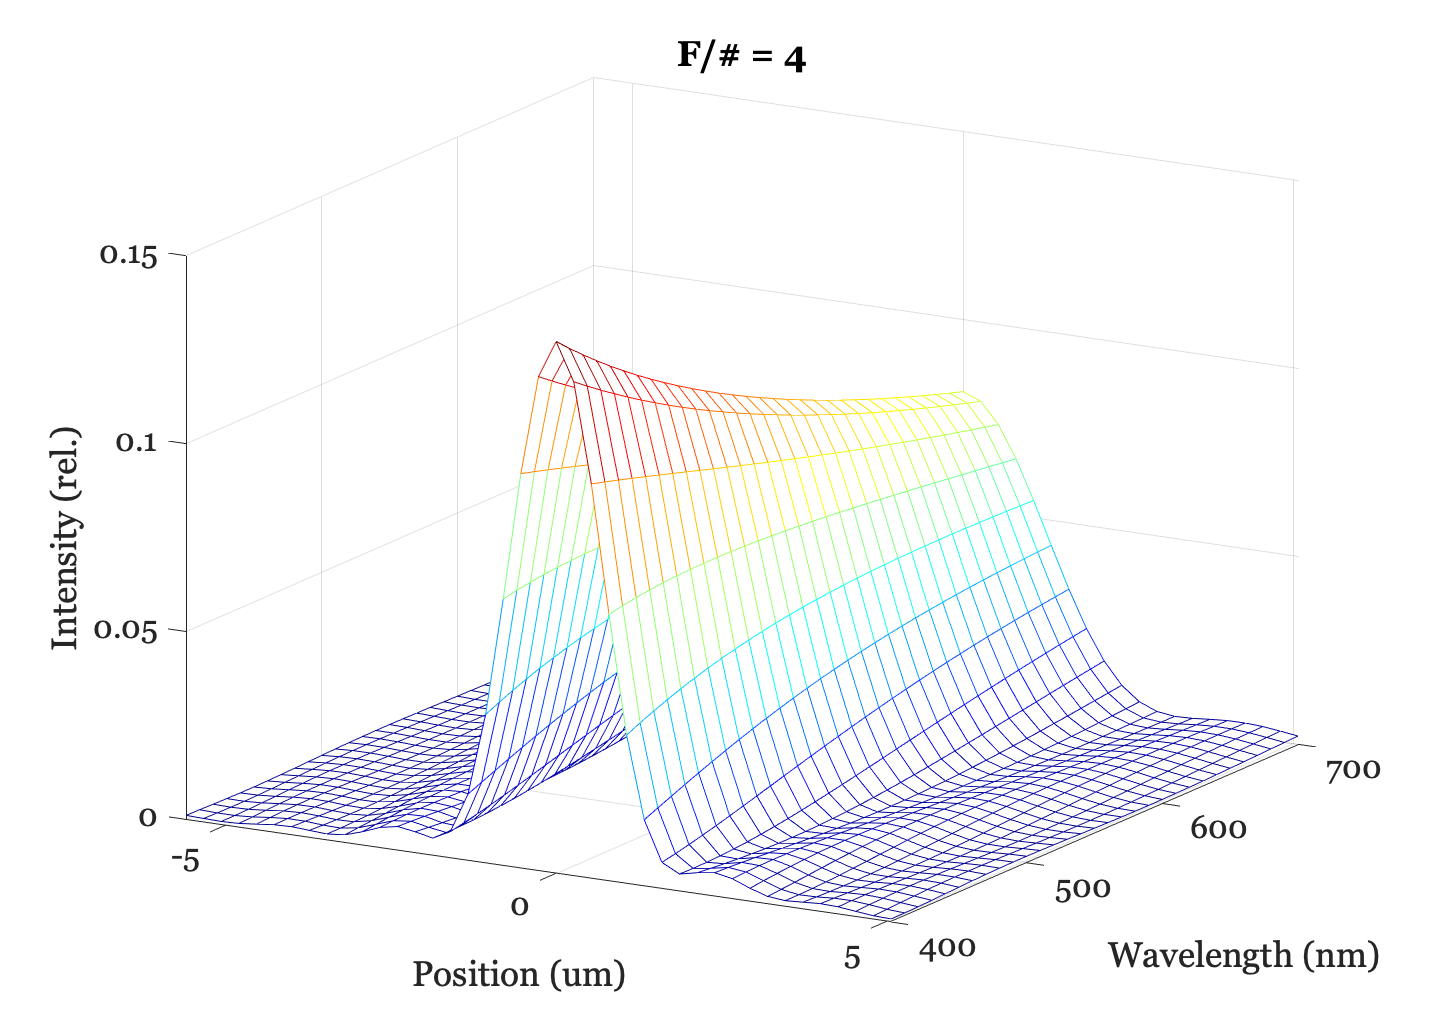

vcNewGraphWin;
uData = oiPlot(oi,'ls wavelength');
title(sprintf('F/# = %.0d',oiGet(oi,'optics f number')))

## Programming note: Notice the data structure returned by oiPlot

uData

uData = struct with fields:
             x: [1×41 double]
    wavelength: [31×1 single]
        lsWave: [31×41 double]
